# 1.1

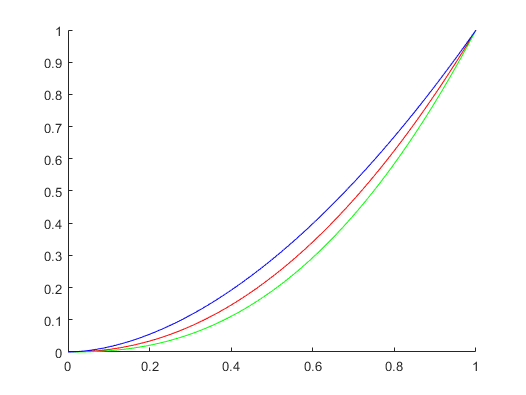

n = length(TRCr);
x = linspace(0,1,n);
hold on
plot(x,TRCr, 'r')
plot(x,TRCg, 'g')
plot(x,TRCb, 'b')

# 1.2

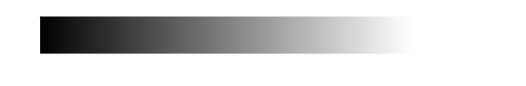

imshow(Ramp_linear)

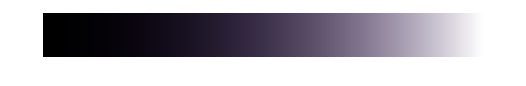

imshow(Ramp_display)

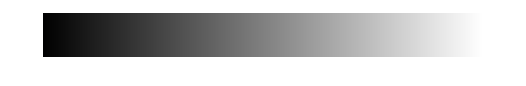


res = linearization(Ramp_display, TRCr, TRCg, TRCb);
imshow(res)

# 1.3

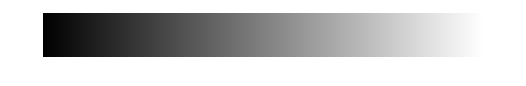

d = gammaCorrection(Ramp_display, [2.1, 2.4, 1.8]);
imshow(d)

# 2.1

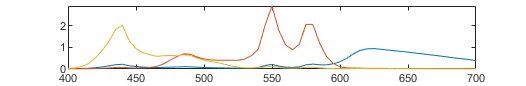

n = length(DLP);
x = linspace(400,700,n);
plot(x,DLP)

# 2.2

S = DLP*RAW_C1_CIED65;

S =     0.0172    0.0077    0.0037    0.0055    0.0141    0.0108    0.0067    0.0018    0.0033    0.0012    0.0043    0.0035    0.0032    0.0028    0.0158    0.0045    0.0141    0.0027    0.0092    0.0103
    0.0317    0.0141    0.0068    0.0101    0.0266    0.0201    0.0124    0.0033    0.0061    0.0023    0.0078    0.0063    0.0059    0.0054    0.0293    0.0082    0.0264    0.0048    0.0172    0.0191
    0.0655    0.0296    0.0145    0.0213    0.0552    0.0422    0.0213    0.0068    0.0100    0.0047    0.0167    0.0127    0.0123    0.0097    0.0635    0.0177    0.0564    0.0091    0.0312    0.0398
    0.1381    0.0628    0.0311    0.0455    0.1178    0.0902    0.0413    0.0144    0.0188    0.0100    0.0353    0.0262    0.0259    0.0196    0.1368    0.0378    0.1216    0.0183    0.0623    0.0843
    0.2817    0.1282    0.0637    0.0932    0.2415    0.1846    0.0818    0.0294    0.0370    0.0204    0.0721    0.0529    0.0526    0.0395    0.2810    0.0773    0.2499    0.0365    0.1248  


% Calculate the k, normalization factor
k = 100 ./ (CIED65 * xyz(:,2));

k = 4.6460

S_XYZ = xyz'*S*k;

S_XYZ =    41.7845   17.0477    7.5401   11.5678   32.7025   23.8955   28.3563    4.1347   15.5250    2.8774    8.8783    9.7363    7.5435   10.9232   29.6815    8.7983   28.1688    8.8580   34.9799   23.8813
   44.6376   17.0281    7.9998   12.1537   38.8430   26.6085   32.2763    4.1763   17.6834    3.0506    7.7797    9.4263    7.2733   13.7376   31.6385    8.1063   32.3585    8.5397   40.5224   25.7416
   56.0398   25.0260   12.4543   18.2454   48.5676   36.5870   18.5113    5.7723    8.7111    4.0315   13.7550   10.5111   10.2682    8.8917   54.5621   14.7853   49.2410    7.4370   27.3553   34.1405



dE = euclidean_distance_xyz(S_XYZ, XYZ_ref);

dE =    23.2314   19.8215    6.6229   10.7843   19.3425   11.1055   51.6380   12.9531   49.1197    9.3144   20.5155   28.6191   18.2980   31.6065    5.5943   17.1405   14.5327   33.7034   46.8862   16.1867



mean(dE)

ans = 22.3508

max(dE)

ans = 51.6380

# 2.3

S = DLP*CAL_DATA_C1_CIED65;

S =     0.0236    0.0105    0.0048    0.0072    0.0184    0.0142    0.0108    0.0025    0.0056    0.0017    0.0060    0.0052    0.0045    0.0042    0.0202    0.0061    0.0179    0.0042    0.0142    0.0139
    0.0434    0.0191    0.0089    0.0133    0.0349    0.0266    0.0199    0.0045    0.0102    0.0031    0.0106    0.0093    0.0082    0.0081    0.0376    0.0109    0.0338    0.0075    0.0264    0.0257
    0.0845    0.0381    0.0181    0.0269    0.0685    0.0529    0.0320    0.0088    0.0158    0.0060    0.0217    0.0174    0.0161    0.0133    0.0780    0.0225    0.0689    0.0133    0.0443    0.0507
    0.1734    0.0787    0.0380    0.0561    0.1432    0.1105    0.0590    0.0182    0.0282    0.0125    0.0447    0.0346    0.0329    0.0258    0.1653    0.0470    0.1462    0.0255    0.0846    0.1048
    0.3504    0.1592    0.0775    0.1140    0.2919    0.2248    0.1148    0.0367    0.0542    0.0252    0.0903    0.0690    0.0663    0.0512    0.3380    0.0953    0.2990    0.0501    0.1669  


% Calculate the k, normalization factor
k = 100 ./ (CIED65 * xyz(:,2));

k = 4.6460

S_XYZ = xyz'*S*k;

S_XYZ =    72.2807   29.4539   12.5261   19.4619   53.9646   39.8703   52.7674    7.1940   29.2126    4.9468   15.5976   17.8078   13.3203   19.4132   47.9787   15.0371   45.2087   16.7045   63.7782   40.7359
   78.1657   29.7796   13.7076   20.9610   66.5643   45.7600   58.7062    7.3337   32.3503    5.3238   13.7368   17.0526   12.8822   24.3877   53.4478   14.0698   54.6543   15.7423   72.9040   44.7461
   72.1722   31.9468   15.6030   23.0034   61.2474   46.1480   27.3179    7.4165   13.3904    5.1619   17.5455   14.1209   13.2784   12.3208   67.4895   18.6141   61.0121   10.5146   38.5919   43.5456



dE = euclidean_distance_xyz(S_XYZ, XYZ_ref);

dE =    11.3933   14.2255   10.5205   11.0705   13.0698   10.5281   33.5351    8.6783   33.4318    5.4378   19.8112   16.1086   12.5781   16.1138   23.4782   19.0947   22.1049   20.3414   27.1078    9.8415



mean(dE)

ans = 16.9236

max(dE)

ans = 33.5351

# 3.1

A = xyz'*DLP*k;
inv(A)

ans =     0.0438   -0.0266   -0.0062
   -0.0108    0.0182    0.0001
   -0.0032   -0.0001    0.0115


# 3.2

xyzValuesFromSpectra = xyz'*( CIED65 .* chips20 )' * k;
D = CAL_DATA_C1_CIED65';
C = xyzValuesFromSpectra';
XYZ_approx = D * (pinv(D)*C);

%dp = A \ XYZ_approx';
dp = A \ XYZ_est;

S = DLP*dp;

k = 100 ./ (CIED65 * xyz(:,2));
S_XYZ = xyz'*S*k;

dE = euclidean_distance_xyz(S_XYZ, XYZ_ref);

mean(dE)

ans = 1.0238

max(dE)

ans = 3.1053

# 3.3

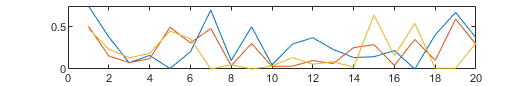

% XYZ_est is not the same as our XYZ_approx from Lab 1 3.4 ??

% Values under 0
plot(dp')

# 3.4

% Set all negative values to 0
dp = (dp > 0).*dp

dp =     0.7491    0.3818    0.0742    0.1615    0.0060    0.2044    0.7004    0.1009    0.5019    0.0495    0.2964    0.3718    0.2326    0.1363    0.1461    0.2187         0    0.4061    0.6730    0.3704
    0.5099    0.1543    0.0773    0.1217    0.4973    0.3095    0.4826    0.0399    0.3035    0.0311    0.0337    0.1004    0.0645    0.2549    0.2897    0.0426    0.3511    0.1029    0.5939    0.2922
    0.4799    0.2366    0.1327    0.1859    0.4524    0.3594         0    0.0501         0    0.0355    0.1350    0.0566    0.0862    0.0218    0.6421    0.1578    0.5430    0.0088    0.0092    0.3111



% Recalculate 
S = DLP*dp;

k = 100 ./ (CIED65 * xyz(:,2));
S_XYZ = xyz'*S*k;

dE = euclidean_distance_xyz(S_XYZ, XYZ_ref);

mean(dE)

ans = 2.8360

max(dE)

ans = 17.8740

# 3.5

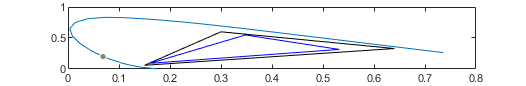

plot_chrom_sRGB(A)

# 3.6

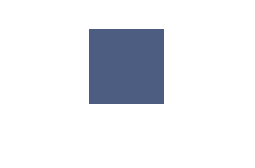

e = CIED65 .* chips20(1,:);
d = Ad'*e';
showRGB(d');

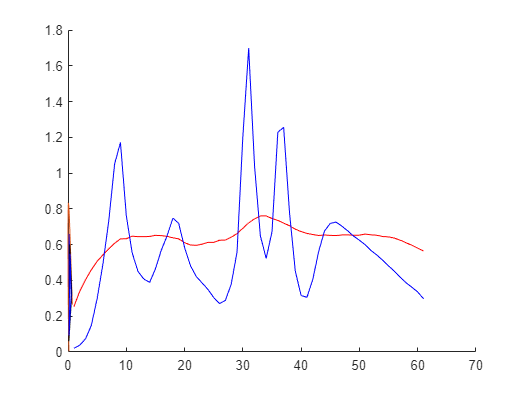

figure
hold on 
plot(e, 'r')
plot(S(:,1), 'b')

plot_chrom_sRGB(d)

A = xyz'*Ad*k;
plot_chrom_sRGB(A);
A = xyz'*DLP*k;
plot_chrom_sRGB(A);

function res = linearization(d, r, g, b)
    res(:,:,1) = interp1(r,linspace(0,1,101),d(:,:,1),'pchip');
    res(:,:,2) = interp1(g,linspace(0,1,101),d(:,:,2),'pchip');
    res(:,:,3) = interp1(b,linspace(0,1,101),d(:,:,3),'pchip');
end

function d = gammaCorrection(dp, g)
    dmax = max(max(dp));
    d(:,:,1) = dmax(1) * (( dp(:,:,1)/dmax(1) ).^(1/g(1)));
    d(:,:,2) = dmax(2) * (( dp(:,:,2)/dmax(2) ).^(1/g(2)));
    d(:,:,3) = dmax(3) * (( dp(:,:,3)/dmax(3) ).^(1/g(3)));
end
